## **Question 1**

- Consider the the Lorenz-63 model with the setting used in Project 1. The data assimilation problem is posed over the interval [0, T], starting with initial background states from N (x b 0 , B0). Observations are available at times ti = i ∆t, i = 0, . . . , N, tN = T. Use your synthetic observations, observation error covariance, and observation operator from Project 1.

**The code below is taken directly from my Project 1 implementation (modified to the L63 system)**

**1.1)**

- Implement the Lorenz-63 model (1) and solve it using a Matlab ode solver (ode45 or one integrator selected from MATLODE).

- Start with an initial condition where the states are drawn from a random distribution (e.g., x0 ∼N (0, 16)), then integrate for 5 time units. Save the result. This is our x[-1]true.

- Propagate for ∆t time units, and save. This is our reference state x[0]true.

- (You can use ∆t = 0.1.)

clear;
close all;
clc;

% Setting seed for reproducibility
rng(38199650)

% Importing Lorenz96 model
m = otp.lorenz63.presets.Canonical;

% Model configurations
n_states = 3;
n_obs_states = 2;

% Inital conditions
x0 = [-10.0375; -4.3845; 34.6514];
B0 = [12.4294, 12.4323, -0.2139; 12.4323, 16.0837, -0.0499; -0.2139, -0.0499, 14.7634];

% Number of assimilation windows
N = 6;
X_a_0 = zeros(3,N);

% Reference solution over assimilation windows
x = x0;
X_ref = zeros(3,N);
dt = 0.1; % time step unit
T = 0:dt:(N*dt)-dt;
X_ref(:, 1) = x;
for i = 1:(length(T)-1)
    [~, x] = ode45(m.RHS.F, [T(i), T(i+1)], x);
    x = x(end, :);
    X_ref(:, i+1) = x;
end

for j = 1:N

    % Time steps
    dt = 0.1; % time step unit
    h = dt/200;
    T_max = 0.2;
    T = (j-1)*dt:dt:T_max+(j-1)*dt;
    
    % Array initalization
    X = zeros(3,round(T_max/dt) + 1);
    
    % iterate through timesteps
    x = x0;
    X(:, 1) = x;
    for i = 1:(length(T)-1)
        [~, x] = ode45(m.RHS.F, [T(i), T(i+1)], x);
        x = x(end, :);
        X(:, i+1) = x;
    end
    
    % Generating observations
    
    n_obs = 1;
    % Apply observation operator and add random noise to reference trajectory
    % Generating observation operator (observing first two states)
    
    % Not 100% on this size (0 x3)
    H = [1, 0, 0;
        0, 1, 0;
        0, 0, 0];
    
    % Applying observation vector to reference trajectory
    % H * Reference -> Observations, Clone Observatations + noise -> ensemble 
    X_obvs = H * X;
    X_obvs_ens = repmat(X_obvs, 1,1, n_obs);
    
    % Generating and applying observation noise (for each ensemble member)
    obvs_sigma = 0.01;
    obvs_noise = normrnd(0,obvs_sigma,size(X_obvs_ens));  % (note normrnd(mu,sigma))
    obvs_noise(3,:,:) = 0;
    X_obvs_ens = X_obvs_ens + obvs_noise;
    
    % Draw X0 from dist
    x0_b = mvnrnd(x0,B0)';

    if j == 1
        x0_b_0 = x0_b % Saving first x0_b for comparison plot
    end

    % Run model with background
    X_b = zeros(3,round(T_max/dt) + 1);
    x = x0_b;
    X_b(:, 1) = x;
    for i = 1:(length(T)-1)
        [~, x] = ode45(m.RHS.F, [T(i), T(i+1)], x);
        x = x(end, :);
        X_b(:, i+1) = x;
    end
    
    %a = x0_b; b = X_obvs_ens; % Assign parameter values
    f = @(x)var4(x,x0_b,X_obvs_ens,T_max,dt);
    
    options = optimoptions('fminunc','Display','iter','Algorithm','trust-region','SpecifyObjectiveGradient',true);
    x = x0_b
    for k = 1:5
        xb = x
        f = @(x)var4(x,xb,X_obvs_ens,T_max,dt);
        [x0_a,fval,exitflag,output] = fminunc(f,x,options)
        x = x0_a
    end

    % Run forward model and update next window x0
    x0, x0_b, x0_a
    X_a = zeros(3,(round(T_max/dt)) + 1);
    x = x0_a;
    X_a(:, 1) = x;
    for i = 1:(length(T)-1)
        [~, x] = ode45(m.RHS.F, [T(i), T(i+1)], x);
        x = x(end, :);
        X_a(:, i+1) = x;
    end
    
    x0 = X_a(:,2);
    X_a_0(:,j) = x0_a; % Save analysis inital state


end

x0_b_0 =   -16.5190
  -10.8205
   33.0062


x =   -16.5190
  -10.8205
   33.0062


xb =   -16.5190
  -10.8205
   33.0062



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0            853.524                           158                
     1            22.0321             10           47.3           1
     2            2.66138        1.07844           3.29           1
     3            2.05911       0.212509           1.39           1
     4            1.94908       0.115064          0.949           1
     5            1.86237         0.0885           1.53           1
     6            1.82647      0.0397874          0.459           1
     7             1.8219      0.0310696          0.368           1
     8            1.79793       0.040933          0.245           1
     9            1.79508      0.0201238          0.187           1
    10            1.78804       0.038347           0.37           1
    11            1.78641      0.0100545         0.0688           1
    12            1.78641     0.00874903        

x0_a =   -10.0718
   -4.3902
   34.6569


fval = 1.7864

exitflag = 2

output = struct with fields:
         iterations: 19
          funcCount: 20
           stepsize: 5.3400e-07
       cgiterations: 13
      firstorderopt: 0.0418
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 5.339987e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.0718
   -4.3902
   34.6569


xb =   -10.0718
   -4.3902
   34.6569



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0         0.00896566                         0.544                
     1         0.00322208      0.0329473          0.202           1
     2         0.00126787      0.0194426          0.171           1
     3        0.000902293     0.00544168         0.0216           1
     4        0.000892976     0.00111047        0.00775           1
     5        0.000892093     0.00049645         0.0042           1

Local minimum possible.

fminunc stopped because the final change in function value relative to 
its initial value is less than the value of the function tolerance.

<

x0_a =   -10.0430
   -4.3984
   34.6766


fval = 8.9209e-04

exitflag = 3

output = struct with fields:
         iterations: 5
          funcCount: 6
           stepsize: 4.9645e-04
       cgiterations: 5
      firstorderopt: 0.0042
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the final change in function value relative to ↵its initial value is less than the value of the function tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative objective function value is changing↵by less than options.FunctionTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.0430
   -4.3984
   34.6766


xb =   -10.0430
   -4.3984
   34.6766



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0        0.000655962                        0.0121                
     1        0.000649809    0.000910107        0.00852           1
     2        0.000637574     0.00134981         0.0161           1
     3        0.000634857    0.000346868        0.00537           1
     4        0.000634857    0.000329985        0.00537           1
     5        0.000634769    8.24962e-05          0.004           0
     6        0.000634765    2.06241e-05        0.00364           1
     7        0.000634764    5.15601e-06        0.00354           1
     8        0.000634764      1.289e-06        0.00354           1
     9        0.000634764    3.22251e-07        0.00354           0

Local minimum possible.

fminunc stopped because the 

x0_a =   -10.0428
   -4.3996
   34.6780


fval = 6.3476e-04

exitflag = 2

output = struct with fields:
         iterations: 9
          funcCount: 10
           stepsize: 3.2225e-07
       cgiterations: 7
      firstorderopt: 0.0035
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 3.222509e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.0428
   -4.3996
   34.6780


xb =   -10.0428
   -4.3996
   34.6780



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0        0.000634396                       0.00396                
     1        0.000634396    0.000239858        0.00396           1
     2        0.000634394    5.99646e-05        0.00293           0
     3        0.000634394    1.49911e-05        0.00293           1
     4        0.000634394    3.74779e-06        0.00293           0
     5        0.000634394    9.36947e-07        0.00293           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the step size tolerance.

<

x0_a =   -10.0427
   -4.3996
   34.6780


fval = 6.3439e-04

exitflag = 2

output = struct with fields:
         iterations: 5
          funcCount: 6
           stepsize: 9.3695e-07
       cgiterations: 2
      firstorderopt: 0.0029
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 9.369468e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.0427
   -4.3996
   34.6780


xb =   -10.0427
   -4.3996
   34.6780



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0        0.000634394                       0.00295                
     1        0.000634394    0.000179311        0.00295           1
     2        0.000634394    4.48277e-05        0.00295           0
     3        0.000634394    1.12069e-05        0.00295           0
     4        0.000634394    2.80173e-06        0.00295           0
     5        0.000634394    7.00433e-07        0.00295           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the step size tolerance.

<

x0_a =   -10.0427
   -4.3996
   34.6780


fval = 6.3439e-04

exitflag = 2

output = struct with fields:
         iterations: 5
          funcCount: 6
           stepsize: 7.0043e-07
       cgiterations: 1
      firstorderopt: 0.0030
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 7.004331e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =   -10.0427
   -4.3996
   34.6780


x0 =   -10.0375
   -4.3845
   34.6514


x0_b =   -16.5190
  -10.8205
   33.0062


x0_a =   -10.0427
   -4.3996
   34.6780


x =     0.5300
    3.0326
   26.6941


xb =     0.5300
    3.0326
   26.6941



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0            2026.73                           637                
     1            165.383             10            122           1
     2            15.9259        3.61021           42.1           1
     3            3.30086        1.38663           5.57           1
     4             1.6501       0.457901           4.22           1
     5             1.5493      0.0559518          0.587           1
     6            1.46367       0.308586           1.27           1
     7            1.44514      0.0467059          0.278           1
     8            1.44449     0.00917261         0.0306           1
     9            1.44449      0.0187835         0.0306           1
    10            1.44442     0.00469588         0.0325           0
    11            1.44442     0.00227973         0.0325           1
    12            1.44442    0.000569934        

x0_a =    -4.9388
   -1.3226
   28.0532


fval = 1.4444

exitflag = 2

output = struct with fields:
         iterations: 17
          funcCount: 18
           stepsize: 5.5658e-07
       cgiterations: 12
      firstorderopt: 0.0258
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 5.565757e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =    -4.9388
   -1.3226
   28.0532


xb =    -4.9388
   -1.3226
   28.0532



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0          0.0209121                         0.715                
     1         0.00350255      0.0483121          0.431           1
     2         0.00263464     0.00523641         0.0227           1
     3         0.00260362      0.0126301         0.0451           1
     4         0.00260362     0.00162242         0.0451           1
     5         0.00260147    0.000405606         0.0257           0
     6         0.00260147    0.000101401         0.0257           1
     7         0.00260147    2.53504e-05         0.0257           0
     8         0.00260147    6.33759e-06         0.0257           0
     9         0.00260147     1.5844e-06         0.0257           0
    10         0.00260147      3.961e-07         0.0257           0

Local minimum possible.

fminunc sto

x0_a =    -4.9837
   -1.3145
   28.0714


fval = 0.0026

exitflag = 2

output = struct with fields:
         iterations: 10
          funcCount: 11
           stepsize: 3.9610e-07
       cgiterations: 5
      firstorderopt: 0.0257
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 3.960995e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =    -4.9837
   -1.3145
   28.0714


xb =    -4.9837
   -1.3145
   28.0714



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0         0.00212718                        0.0438                
     1         0.00212718     0.00346668         0.0438           1
     2         0.00212718     0.00086667         0.0438           0
     3         0.00212588    0.000216668         0.0374           0
     4         0.00212552    5.41669e-05         0.0361           1
     5         0.00212544    1.35417e-05         0.0358           1
     6         0.00212542    3.38543e-06         0.0357           1
     7         0.00212542    8.46357e-07         0.0357           1

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a =    -4.9840
   -1.3144
   28.0714


fval = 0.0021

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 8.4636e-07
       cgiterations: 5
      firstorderopt: 0.0357
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 8.463574e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =    -4.9840
   -1.3144
   28.0714


xb =    -4.9840
   -1.3144
   28.0714



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0          0.0021254                        0.0358                
     1          0.0021254     0.00214378         0.0358           1
     2         0.00212344    0.000535946         0.0269           0
     3         0.00212344    0.000133986         0.0269           1
     4         0.00212344    3.34966e-05         0.0269           0
     5         0.00212344    8.37415e-06         0.0269           0
     6         0.00212344    2.09354e-06         0.0269           0
     7         0.00212344    5.23384e-07         0.0269           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a =    -4.9845
   -1.3143
   28.0714


fval = 0.0021

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 5.2338e-07
       cgiterations: 2
      firstorderopt: 0.0269
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 5.233844e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =    -4.9845
   -1.3143
   28.0714


xb =    -4.9845
   -1.3143
   28.0714



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0         0.00212337                        0.0271                
     1         0.00212337      0.0015995         0.0271           1
     2         0.00212337    0.000399874         0.0271           0
     3         0.00212337    9.99685e-05         0.0271           0
     4         0.00212337    2.49921e-05         0.0271           0
     5         0.00212337    6.24803e-06         0.0271           0
     6         0.00212337    1.56201e-06         0.0271           0
     7         0.00212337    3.90502e-07         0.0271           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a =    -4.9845
   -1.3143
   28.0714


fval = 0.0021

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 3.9050e-07
       cgiterations: 1
      firstorderopt: 0.0271
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 3.905021e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =    -4.9845
   -1.3143
   28.0714


x0 =    -4.9778
   -1.3101
   28.0640


x0_b =     0.5300
    3.0326
   26.6941


x0_a =    -4.9845
   -1.3143
   28.0714


x =    -1.2261
   -1.9008
   18.0600


xb =    -1.2261
   -1.9008
   18.0600



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0            38.8419                          78.2                
     1             28.938        3.36356           8.04           1
     2            25.8226        1.15445           25.9           1
     3            16.0112        1.63032           12.9           1
     4            8.91694        7.57254           13.8           1
     5            4.23715        1.92665           8.58           1
     6            1.34345        0.58022            1.3           1
     7           0.918515       0.681003           2.49           1
     8           0.894737       0.020881           1.28           1
     9           0.858162      0.0682984          0.387           1
    10           0.857495      0.0034172          0.121           1
    11           0.852895       0.058407          0.143           1
    12           0.852166      0.0100818        

x0_a =    -2.8469
   -2.1860
   21.9011


fval = 0.8521

exitflag = 2

output = struct with fields:
         iterations: 20
          funcCount: 21
           stepsize: 9.2996e-07
       cgiterations: 14
      firstorderopt: 0.0101
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 9.299595e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =    -2.8469
   -2.1860
   21.9011


xb =    -2.8469
   -2.1860
   21.9011



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0          0.0244064                         0.484                
     1         0.00218105       0.108328           0.33           1
     2         0.00124598      0.0186405          0.119           1
     3         0.00118126     0.00172771         0.0558           1
     4         0.00114752     0.00294951         0.0114           1
     5         0.00112342     0.00491809         0.0173           1
     6         0.00112298    0.000836941         0.0168           1
     7         0.00112103    0.000209235        0.00884           1
     8         0.00112103    0.000494209        0.00884           1
     9         0.00112103    0.000104618        0.00884           0
    10         0.00112103    2.61544e-05        0.00884           0
    11         0.00112103     6.5386e-06        0.00851           0
    12         0.00112103    1.63465e-06        

x0_a =    -2.8904
   -2.1934
   22.0175


fval = 0.0011

exitflag = 2

output = struct with fields:
         iterations: 13
          funcCount: 14
           stepsize: 4.0866e-07
       cgiterations: 10
      firstorderopt: 0.0084
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.086625e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x =    -2.8904
   -2.1934
   22.0175


xb =    -2.8904
   -2.1934
   22.0175



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0        0.000425989                        0.0213                
     1        0.000413782     0.00164431        0.00684           1
     2        0.000405014     0.00220571         0.0108           1
     3        0.000404217    0.000124149        0.00537           1

Local minimum possible.

fminunc stopped because the final change in function value relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


x0_a =    -2.8917
   -2.1934
   22.0203


fval = 4.0422e-04

exitflag = 3

output = struct with fields:
         iterations: 3
          funcCount: 4
           stepsize: 1.2415e-04
       cgiterations: 3
      firstorderopt: 0.0054
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the final change in function value relative to ↵its initial value is less than the value of the function tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative objective function value is changing↵by less than options.FunctionTolerance = 1.000000e-06.'
    constrviolation: []


x =    -2.8917
   -2.1934
   22.0203


xb =    -2.8917
   -2.1934
   22.0203



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0        0.000403688                       0.00581                
     1        0.000403688    0.000300549        0.00581           1
     2        0.000403688    7.51372e-05        0.00581           0
     3        0.000403688    1.87843e-05        0.00581           0
     4        0.000403688    4.69608e-06        0.00581           0
     5        0.000403688    1.17402e-06        0.00581           0
     6        0.000403688    2.93505e-07        0.00581           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the step size tolerance.

<

x0_a = 3×1
   -2.8917
   -2.1934
   22.0203


fval = 4.0369e-04

exitflag = 2

output = struct with fields:
         iterations: 6
          funcCount: 7
           stepsize: 2.9350e-07
       cgiterations: 1
      firstorderopt: 0.0058
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 2.935049e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x = 3×1
   -2.8917
   -2.1934
   22.0203


xb = 3×1
   -2.8917
   -2.1934
   22.0203



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0        0.000403688                       0.00581                
     1        0.000403688    0.000300549        0.00581           1
     2        0.000403688    7.51372e-05        0.00581           0
     3        0.000403688    1.87843e-05        0.00581           0
     4        0.000403688    4.69608e-06        0.00581           0
     5        0.000403688    1.17402e-06        0.00581           0
     6        0.000403688    2.93505e-07        0.00581           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the step size tolerance.

<

x0_a = 3×1
   -2.8917
   -2.1934
   22.0203


fval = 4.0369e-04

exitflag = 2

output = struct with fields:
         iterations: 6
          funcCount: 7
           stepsize: 2.9350e-07
       cgiterations: 1
      firstorderopt: 0.0058
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 2.935049e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x = 3×1
   -2.8917
   -2.1934
   22.0203


x0 = 3×1
   -2.9070
   -2.1915
   22.0137


x0_b = 3×1
   -1.2261
   -1.9008
   18.0600


x0_a = 3×1
   -2.8917
   -2.1934
   22.0203


x = 3×1
   -1.3273
   -1.9160
   19.5550


xb = 3×1
   -1.3273
   -1.9160
   19.5550



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0            1014.68                           598                
     1              204.5             10            101           1
     2              204.5             10            101           1
     3              204.5            2.5            101           0
     4            114.402          0.625             62           0
     5            72.7873           1.25           39.2           1
     6            50.9581            2.5           42.8           1
     7            29.3248            2.5           34.7           1
     8            17.1189            2.5             36           1
     9            2.90122       0.976608           11.4           1
    10            1.35998       0.933053           8.87           1
    11           0.500272       0.311587           3.08           1
    12           0.309782       0.160359        

x0_a = 3×1
   -3.1483
   -4.2700
   17.6578


fval = 0.2972

exitflag = 2

output = struct with fields:
         iterations: 40
          funcCount: 41
           stepsize: 8.7164e-07
       cgiterations: 38
      firstorderopt: 0.1077
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 8.716369e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x = 3×1
   -3.1483
   -4.2700
   17.6578


xb = 3×1
   -3.1483
   -4.2700
   17.6578



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0         0.00198449                         0.237                
     1         0.00186363      0.0297266          0.298           1
     2        0.000908997     0.00843905         0.0631           1
     3        0.000764079      0.0046388         0.0371           1
     4        0.000752825    0.000900402        0.00996           1
     5        0.000752825     0.00164346        0.00996           1
     6        0.000752825    0.000410866        0.00996           0
     7        0.000752825    0.000102716        0.00996           0
     8        0.000752825    2.56791e-05        0.00996           0
     9        0.000752825    6.41978e-06        0.00996           0
    10        0.000752825    1.60495e-06        0.00996           0
    11        0.000752825    4.01236e-07        0.00996           0



x0_a = 3×1
   -3.1458
   -4.2673
   17.6380


fval = 7.5283e-04

exitflag = 2

output = struct with fields:
         iterations: 11
          funcCount: 12
           stepsize: 4.0124e-07
       cgiterations: 5
      firstorderopt: 0.0100
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.012363e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x = 3×1
   -3.1458
   -4.2673
   17.6380


xb = 3×1
   -3.1458
   -4.2673
   17.6380



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0        0.000739343                        0.0113                
     1        0.000739343     0.00183144         0.0113           1
     2        0.000739343    0.000457861         0.0113           0
     3        0.000739343    0.000114465         0.0113           0
     4        0.000739343    2.86163e-05         0.0113           0
     5        0.000739343    7.15408e-06         0.0113           0
     6        0.000739343    1.78852e-06         0.0113           0
     7        0.000739343     4.4713e-07         0.0113           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a = 3×1
   -3.1458
   -4.2673
   17.6380


fval = 7.3934e-04

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.4713e-07
       cgiterations: 1
      firstorderopt: 0.0113
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.471300e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x = 3×1
   -3.1458
   -4.2673
   17.6380


xb = 3×1
   -3.1458
   -4.2673
   17.6380



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0        0.000739343                        0.0113                
     1        0.000739343     0.00183144         0.0113           1
     2        0.000739343    0.000457861         0.0113           0
     3        0.000739343    0.000114465         0.0113           0
     4        0.000739343    2.86163e-05         0.0113           0
     5        0.000739343    7.15408e-06         0.0113           0
     6        0.000739343    1.78852e-06         0.0113           0
     7        0.000739343     4.4713e-07         0.0113           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a = 3×1
   -3.1458
   -4.2673
   17.6380


fval = 7.3934e-04

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.4713e-07
       cgiterations: 1
      firstorderopt: 0.0113
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.471300e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x = 3×1
   -3.1458
   -4.2673
   17.6380


xb = 3×1
   -3.1458
   -4.2673
   17.6380



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0        0.000739343                        0.0113                
     1        0.000739343     0.00183144         0.0113           1
     2        0.000739343    0.000457861         0.0113           0
     3        0.000739343    0.000114465         0.0113           0
     4        0.000739343    2.86163e-05         0.0113           0
     5        0.000739343    7.15408e-06         0.0113           0
     6        0.000739343    1.78852e-06         0.0113           0
     7        0.000739343     4.4713e-07         0.0113           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a = 3×1
   -3.1458
   -4.2673
   17.6380


fval = 7.3934e-04

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.4713e-07
       cgiterations: 1
      firstorderopt: 0.0113
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.471300e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x = 3×1
   -3.1458
   -4.2673
   17.6380


x0 = 3×1
   -3.1482
   -4.2745
   17.6714


x0_b = 3×1
   -1.3273
   -1.9160
   19.5550


x0_a = 3×1
   -3.1458
   -4.2673
   17.6380


x = 3×1
   -6.3645
  -11.0751
   14.8118


xb = 3×1
   -6.3645
  -11.0751
   14.8118



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0            360.825                           112                
     1            59.9992        4.62172           50.2           1
     2            30.2807        2.73903           27.8           1
     3            7.06883        1.73703             20           1
     4            4.27769       0.916829           10.9           1
     5            1.35596        0.63276           6.47           1
     6            1.00705       0.335574           3.35           1
     7           0.584624       0.271491           3.18           1
     8            0.51679       0.137272           1.62           1
     9           0.445604       0.103178           1.05           1
    10            0.43344      0.0507332          0.509           1
    11           0.423722      0.0433801          0.497           1
    12           0.423341      0.0207137        

x0_a = 3×1
   -5.1889
   -8.3542
   15.7407


fval = 0.4205

exitflag = 2

output = struct with fields:
         iterations: 22
          funcCount: 23
           stepsize: 8.3829e-07
       cgiterations: 17
      firstorderopt: 0.0364
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 8.382874e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x = 3×1
   -5.1889
   -8.3542
   15.7407


xb = 3×1
   -5.1889
   -8.3542
   15.7407



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0          0.0115054                         0.394                
     1         0.00447157      0.0256238           0.11           1
     2         0.00447157      0.0113702           0.11           1
     3          0.0044118     0.00284254          0.102           0
     4         0.00436357    0.000710635         0.0948           1
     5         0.00431016    0.000710635          0.087           1
     6         0.00421131     0.00142127         0.0704           1
     7         0.00407141     0.00284254         0.0356           1
     8         0.00401464     0.00378989         0.0274           1
     9         0.00395762     0.00173855         0.0146           1
    10         0.00395401     0.00046874        0.00525           1
    11         0.00395401    0.000505984        0.00525           1
    12         0.00395401    0.000126496        

x0_a = 3×1
   -5.2092
   -8.3334
   15.7339


fval = 0.0040

exitflag = 2

output = struct with fields:
         iterations: 16
          funcCount: 17
           stepsize: 4.9413e-07
       cgiterations: 10
      firstorderopt: 0.0052
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.941250e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x = 3×1
   -5.2092
   -8.3334
   15.7339


xb = 3×1
   -5.2092
   -8.3334
   15.7339



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0         0.00370426                        0.0115                
     1         0.00370426       0.001362         0.0115           1
     2         0.00370089      0.0003405        0.00647           0
     3         0.00369983       0.000681        0.00334           1
     4         0.00369983     0.00017025        0.00334           1
     5         0.00369948    4.25625e-05        0.00262           0

Local minimum possible.

fminunc stopped because the final change in function value relative to 
its initial value is less than the value of the function tolerance.

<

x0_a = 3×1
   -5.2098
   -8.3329
   15.7332


fval = 0.0037

exitflag = 3

output = struct with fields:
         iterations: 5
          funcCount: 6
           stepsize: 4.2563e-05
       cgiterations: 3
      firstorderopt: 0.0026
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the final change in function value relative to ↵its initial value is less than the value of the function tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative objective function value is changing↵by less than options.FunctionTolerance = 1.000000e-06.'
    constrviolation: []


x = 3×1
   -5.2098
   -8.3329
   15.7332


xb = 3×1
   -5.2098
   -8.3329
   15.7332



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0         0.00369928                       0.00297                
     1         0.00369928    0.000258376        0.00297           1
     2         0.00369888     6.4594e-05        0.00204           0

Local minimum possible.

fminunc stopped because the final change in function value relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


x0_a = 3×1
   -5.2098
   -8.3329
   15.7331


fval = 0.0037

exitflag = 3

output = struct with fields:
         iterations: 2
          funcCount: 3
           stepsize: 6.4594e-05
       cgiterations: 1
      firstorderopt: 0.0020
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the final change in function value relative to ↵its initial value is less than the value of the function tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative objective function value is changing↵by less than options.FunctionTolerance = 1.000000e-06.'
    constrviolation: []


x = 3×1
   -5.2098
   -8.3329
   15.7331


xb = 3×1
   -5.2098
   -8.3329
   15.7331



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0         0.00369888                       0.00206                
     1         0.00369888    0.000223948        0.00206           1
     2         0.00369863     5.5987e-05        0.00138           0

Local minimum possible.

fminunc stopped because the final change in function value relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


x0_a = 3×1
   -5.2098
   -8.3329
   15.7331


fval = 0.0037

exitflag = 3

output = struct with fields:
         iterations: 2
          funcCount: 3
           stepsize: 5.5987e-05
       cgiterations: 1
      firstorderopt: 0.0014
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the final change in function value relative to ↵its initial value is less than the value of the function tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative objective function value is changing↵by less than options.FunctionTolerance = 1.000000e-06.'
    constrviolation: []


x = 3×1
   -5.2098
   -8.3329
   15.7331


x0 = 3×1
   -5.2095
   -8.3381
   15.7671


x0_b = 3×1
   -6.3645
  -11.0751
   14.8118


x0_a = 3×1
   -5.2098
   -8.3329
   15.7331


x = 3×1
   -7.5960
  -14.1583
   17.2993


xb = 3×1
   -7.5960
  -14.1583
   17.2993



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0            133.077                          67.8                
     1            7.43992        3.18973           15.1           1
     2           0.919006        0.65247              4           1
     3           0.571412        0.20396            1.4           1
     4           0.527737      0.0491694          0.226           1
     5           0.526689     0.00925697          0.103           1
     6           0.526443     0.00308837        0.00371           1
     7           0.526443    0.000303992        0.00371           1
     8           0.526443    7.59981e-05        0.00371           0
     9           0.526443    1.89995e-05        0.00371           0
    10           0.526443    4.74988e-06        0.00371           0
    11           0.526443    1.18747e-06        0.00371           0
    12           0.526443    2.96867e-07        

x0_a = 3×1
   -9.5285
  -14.9550
   19.7548


fval = 0.5264

exitflag = 2

output = struct with fields:
         iterations: 12
          funcCount: 13
           stepsize: 2.9687e-07
       cgiterations: 7
      firstorderopt: 0.0037
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 2.968674e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x = 3×1
   -9.5285
  -14.9550
   19.7548


xb = 3×1
   -9.5285
  -14.9550
   19.7548



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0         0.00872157                         0.453                
     1          0.0011343      0.0249953         0.0306           1
     2          0.0011343     0.00147239         0.0306           1
     3          0.0011343    0.000368098         0.0306           0
     4          0.0011343    9.20246e-05         0.0306           0
     5          0.0011343    2.30061e-05         0.0306           0
     6          0.0011343    5.75153e-06         0.0306           0
     7          0.0011343    1.43788e-06         0.0306           0
     8          0.0011343    3.59471e-07         0.0306           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the

x0_a = 3×1
   -9.5482
  -14.9398
   19.7573


fval = 0.0011

exitflag = 2

output = struct with fields:
         iterations: 8
          funcCount: 9
           stepsize: 3.5947e-07
       cgiterations: 2
      firstorderopt: 0.0306
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 3.594709e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x = 3×1
   -9.5482
  -14.9398
   19.7573


xb = 3×1
   -9.5482
  -14.9398
   19.7573



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0        0.000951856                        0.0401                
     1        0.000951856     0.00180183         0.0401           1
     2        0.000951856    0.000450458         0.0401           0
     3        0.000951856    0.000112615         0.0401           0
     4        0.000951856    2.81536e-05         0.0401           0
     5        0.000951856    7.03841e-06         0.0401           0
     6        0.000951856     1.7596e-06         0.0401           0
     7        0.000951856    4.39901e-07         0.0401           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a = 3×1
   -9.5482
  -14.9398
   19.7573


fval = 9.5186e-04

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.3990e-07
       cgiterations: 1
      firstorderopt: 0.0401
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.399007e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x = 3×1
   -9.5482
  -14.9398
   19.7573


xb = 3×1
   -9.5482
  -14.9398
   19.7573



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0        0.000951856                        0.0401                
     1        0.000951856     0.00180183         0.0401           1
     2        0.000951856    0.000450458         0.0401           0
     3        0.000951856    0.000112615         0.0401           0
     4        0.000951856    2.81536e-05         0.0401           0
     5        0.000951856    7.03841e-06         0.0401           0
     6        0.000951856     1.7596e-06         0.0401           0
     7        0.000951856    4.39901e-07         0.0401           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a = 3×1
   -9.5482
  -14.9398
   19.7573


fval = 9.5186e-04

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.3990e-07
       cgiterations: 1
      firstorderopt: 0.0401
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.399007e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x = 3×1
   -9.5482
  -14.9398
   19.7573


xb = 3×1
   -9.5482
  -14.9398
   19.7573



                                Norm of      First-order 
 Iteration        f(x)          step          optimality   CG-iterations
     0        0.000951856                        0.0401                
     1        0.000951856     0.00180183         0.0401           1
     2        0.000951856    0.000450458         0.0401           0
     3        0.000951856    0.000112615         0.0401           0
     4        0.000951856    2.81536e-05         0.0401           0
     5        0.000951856    7.03841e-06         0.0401           0
     6        0.000951856     1.7596e-06         0.0401           0
     7        0.000951856    4.39901e-07         0.0401           0

Local minimum possible.

fminunc stopped because the size of the current step is less than
the value of the 

x0_a = 3×1
   -9.5482
  -14.9398
   19.7573


fval = 9.5186e-04

exitflag = 2

output = struct with fields:
         iterations: 7
          funcCount: 8
           stepsize: 4.3990e-07
       cgiterations: 1
      firstorderopt: 0.0401
          algorithm: 'trust-region'
            message: 'Local minimum possible.↵↵fminunc stopped because the size of the current step is less than↵the value of the step size tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the norm of the current step, 4.399007e-07, is↵less than options.StepTolerance = 1.000000e-06.'
    constrviolation: []


x = 3×1
   -9.5482
  -14.9398
   19.7573


x0 = 3×1
   -9.5621
  -14.9454
   19.7436


x0_b = 3×1
   -7.5960
  -14.1583
   17.2993


x0_a = 3×1
   -9.5482
  -14.9398
   19.7573


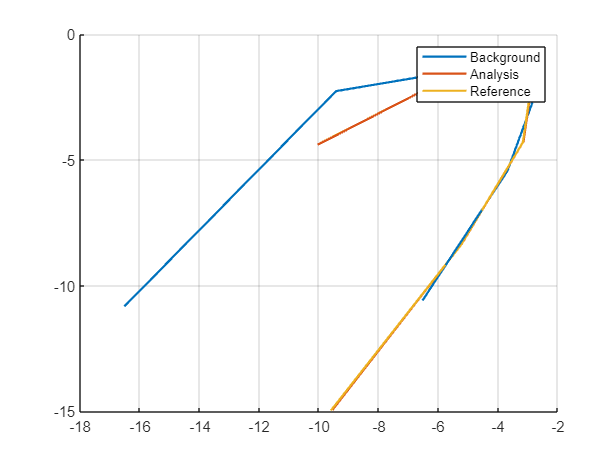

%Generating x0_b_0 trajectory for comparison (traj based on inital x0_b
%draw)

x = x0_b_0;
X_b_0 = zeros(3,N);
dt = 0.1; % time step unit
T = 0:dt:(N*dt)-dt;
X_b_0(:, 1) = x;
for i = 1:(length(T)-1)
    [~, x] = ode45(m.RHS.F, [T(i), T(i+1)], x);
    x = x(end, :);
    X_b_0(:, i+1) = x;
end

clf
hold on
plot3(X_b_0(1, :), X_b_0(2, :), X_b_0(3, :),'linewidth',1.5,'DisplayName', 'Background');
plot3(X_a_0(1, :), X_a_0(2, :), X_a_0(3, :),'linewidth',1.5,'DisplayName', 'Analysis');
plot3(X_ref(1, :), X_ref(2, :), X_ref(3, :),'linewidth',1.5,'DisplayName', 'Reference');
grid on
legend

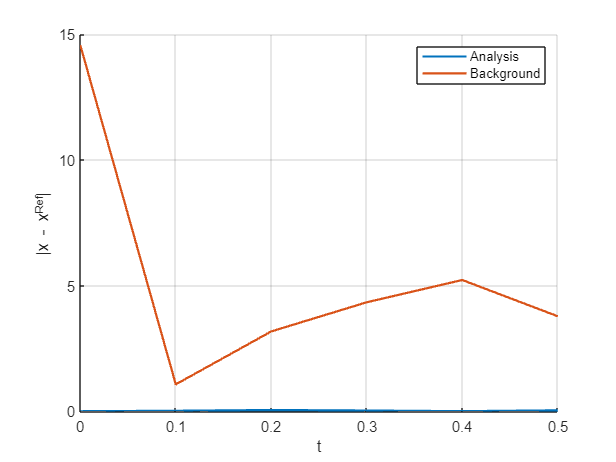

clf
hold on
plot(T,(abs(sum(X_a_0-X_ref,1))), 'linewidth',1.5, 'DisplayName', 'Analysis');
plot(T,(abs(sum(X_b_0-X_ref,1))), 'linewidth',1.5, 'DisplayName', 'Background');
xlabel('t') ;
ylabel('|x - x^{Ref}|');
xlim([T(1),T(end)]);
legend
grid on

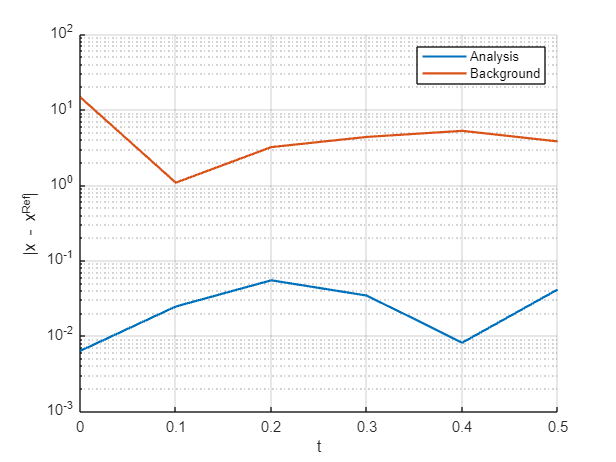

clf
hold on
plot(T,(abs(sum(X_a_0-X_ref,1))), 'linewidth',1.5, 'DisplayName', 'Analysis');
plot(T,(abs(sum(X_b_0-X_ref,1))), 'linewidth',1.5, 'DisplayName', 'Background');
xlabel('t') ;
ylabel('|x - x^{Ref}|');
xlim([T(1),T(end)]);
set(gca,'yscale','log')
legend
grid on

Q2: